# Supervised Learning - Week 1

Supervised learning working principle could be summarized with a block diagram as follows.

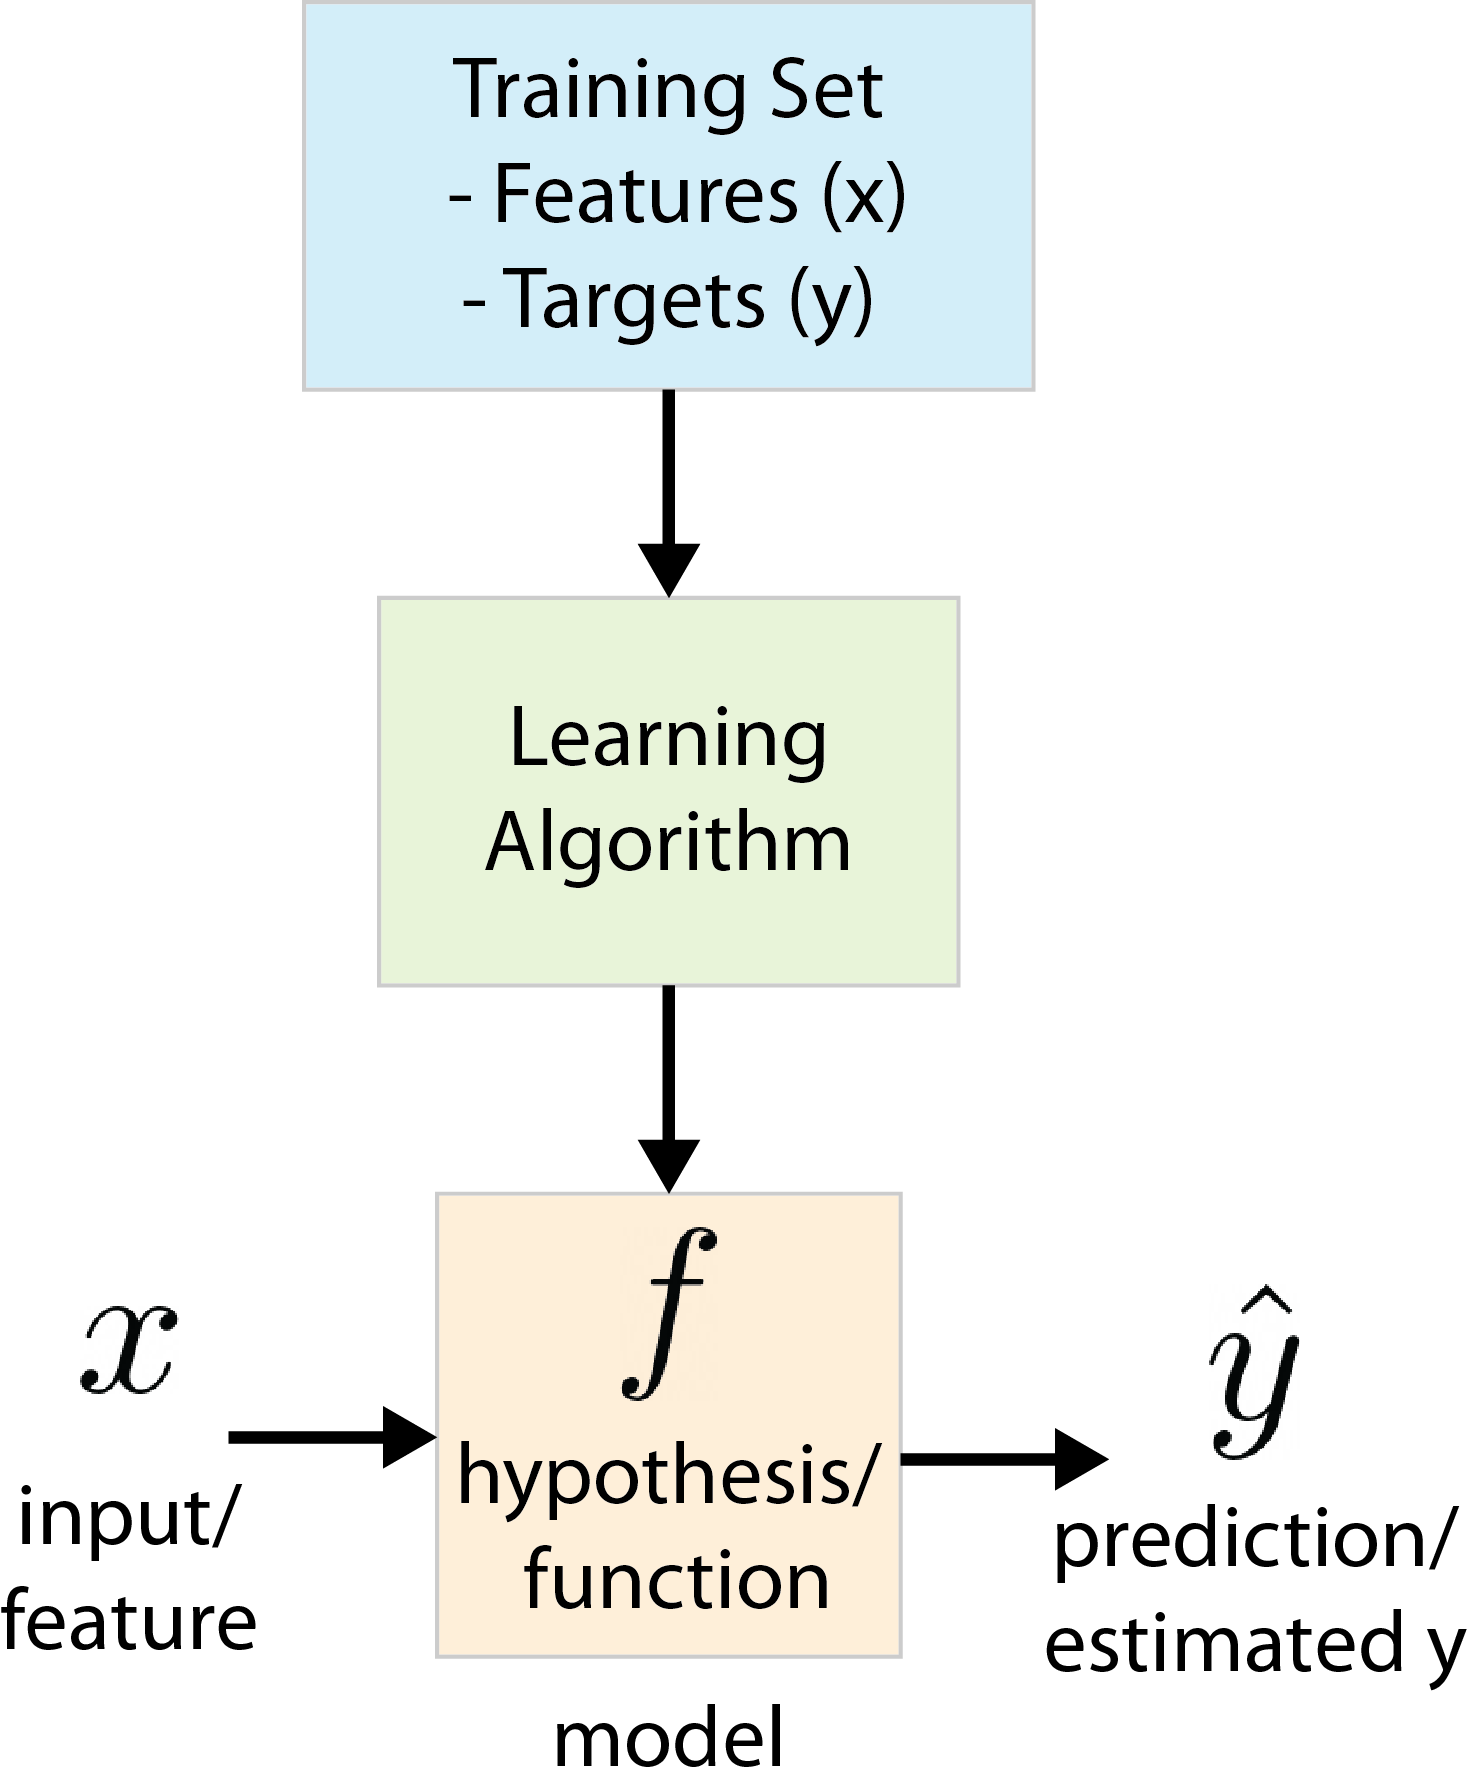

Here, the key questions is:

- How are we going to represent $f$?

- What is the formula we will use to calculate $f$?

## Linear Regression

Let's assume that we have a linear regression application, this would mean that $f_{w,b}(x) = f(x) = wx + b $, where $w$ and $b$ represent the weights and bias, respectively. Why we are choosing $f$ as a linear function (straight line) instead of some non-linear function curve, parabola etc.? Since a linear function is relatively simple and easy to work with. let's use a line as a foundation. This particular model is called univariate linear regresssion (single input/feature x).

The big question in any AIML application is "how to measure how well the model fits the data?". Loss function, is our reference point for evaluating the model performance.

Squared error loss function for a univariate linear regression problem could be given by


$$J(w,b) = \frac{1}{2m}\sum_{i=1}^{m}\left( f_{w,b}(x)-y^{(i)} \right)^2=\frac{1}{2m}\sum_{i=1}^{m}\left( wx^{(i)}+b-y^{(i)} \right)^2 \quad \quad (1)$$


In the AIML area, the coefficient $1/2m$ is adopted for the sake of simplicity in the calculations.

Let's simplify the cost function for a brief moment and assume that $b=0$. Hence, the cost function in (1) reduces to


$$J(w) = \frac{1}{2m}\sum_{i=1}^{m} \left( wx^{(i)}-y^{(i)} \right)^2 \quad\quad (2)$$


where $f_w(x) = wx$. Let's assume that the data fits into the following function $y = x$. If we plot the data points, where the number of training examples $m=5$,

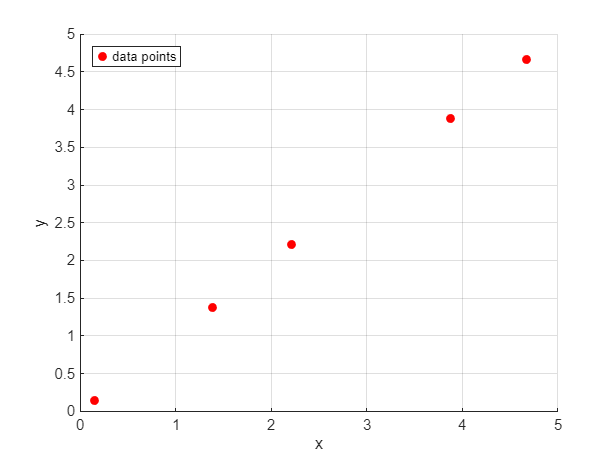

clear all;
close all;
clc;
clf;

% Let's assume we have the following data points
x = [0.15 1.38 2.21 3.88 4.67]; % features
y = x; % targets

figure
scatter(x,y,'ro','filled');
legend('data points',"Location","northwest");
grid on
xlabel('x')
ylabel('y')

Now, we can plot $f_w(x)$ for the weights that falls in the range  $-a \leq w \leq a$, where $a = 2$. Note that we already know that the true weight is $w=1$, however, our aim to approximate the true weight value by solely using the available data. If we plot $f_w(x)$and $J(w)$ with respect to $w$.

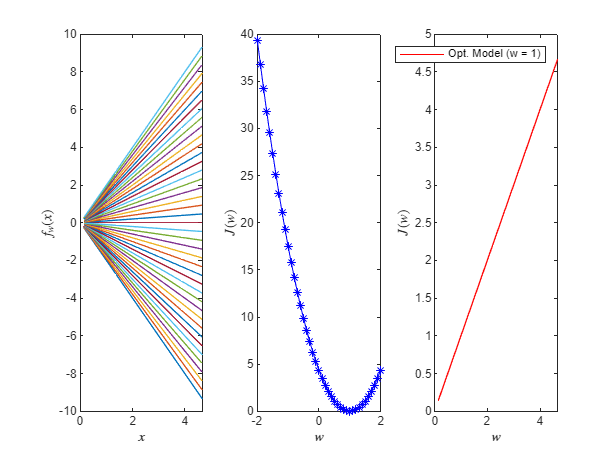

% Let's scan various values of w and calculate the loss
w_vec = -2:0.1:2; % weights

f = [];
J = [];
for i = 1:numel(w_vec)
    w = w_vec(i);
    
    f(i,:) = w.*x;
    J(i,:) = (1/(2*length(x)))*sum((f(i,:)-y).^2);
end

figure
tiledlayout(1,3)
nexttile
plot(x,f);
xlabel('$x$','Interpreter','latex');
ylabel('$f_w(x)$','Interpreter','latex');
xlim([0 max(x)]);

nexttile
plot(w_vec,J,'b-*','LineWidth',0.7)
xlabel('$w$','Interpreter','latex');
ylabel('$J(w)$','Interpreter','latex');

nexttile
plot(x,f(w_vec==w_vec(J==min(J)),:),'r');
xlabel('$w$','Interpreter','latex');
ylabel('$J(w)$','Interpreter','latex');
legend(['Opt. Model (w = ',num2str(w_vec(J==min(J))),')']);
xlim([0 max(x)]);

In summary, we have the following:

**Model:** $f_{w,b}(x) = wx+b$

**Parameters:** $w,b$

**Cost Function:** $J(w,b)=\frac{1}{2m}\sum_{i=1}^{m}\left( wx^{(i)}+b-y^{(i)}\right)^2$

**Objective:** $\underset{w,b}{\mathrm{minimize}}\left\{ J(w,b) \right\} = \underset{w,b}{\mathrm{minimize}}\left\{ \frac{1}{2m}\sum_{i=1}^{m}  \left( wx^{(i)}+b- y^{(i)}\right)^2 \right\}$

Note that minimizing the squared loss is also referred to as **least squares fit**.

Let's go back to the original example and do the same thing without setting $b=0$. Let's look at the house sizes and prices dataset

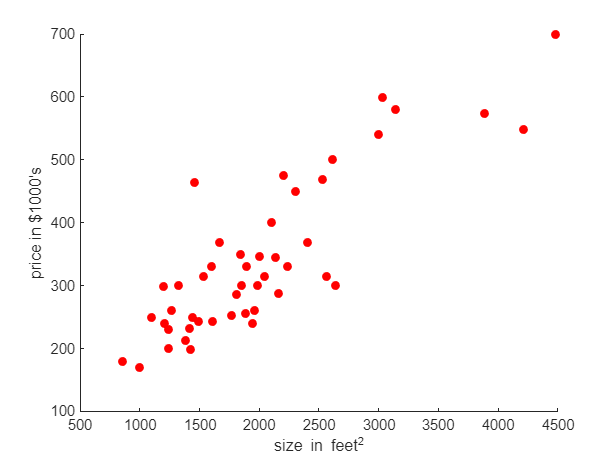

data = importdata("house_sizes_and_prices_dataset.txt"); % Load the data (size (sq. feet) versus price ($))
data(:,2) = []; % Number of bedrooms is not needed in this application
data(:,2) = data(:,2)/1000; % range simplification ($1000's)

% Visualize the data
figure
scatter(data(:,1),data(:,2),'ro','filled');
xlabel("size in feet^2")
ylabel("price in $1000's")

One possible function is $f_{w,b}(x)=0.06x+50$, which is plotted as

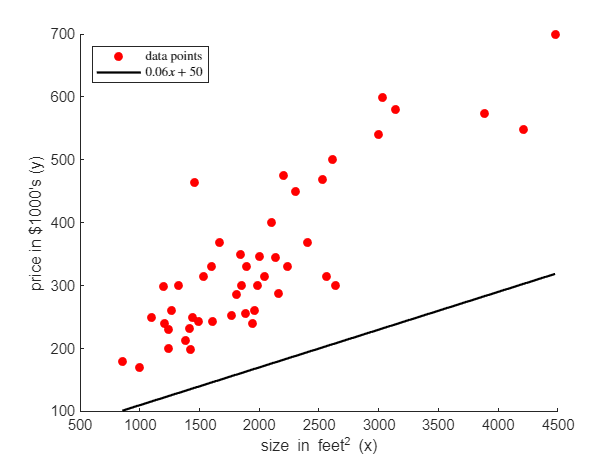

% Visualize the data and the model
figure
scatter(data(:,1),data(:,2),'ro','filled');
hold on
plot(data(:,1),0.06.*data(:,1)+50,'k-','LineWidth',1.5)
hold off
xlabel("size in feet^2 (x)")
ylabel("price in $1000's (y)")
legend(["data points","$0.06x+50$"],"Interpreter","latex","Location","northwest")

Note that this is not a particularly a good model, on the contrary, this is a pretty bad model since it consistently underestimates the housing prices. Let's look at what the cost function $J_{w,b}(x)$ looks like for the given scenario.

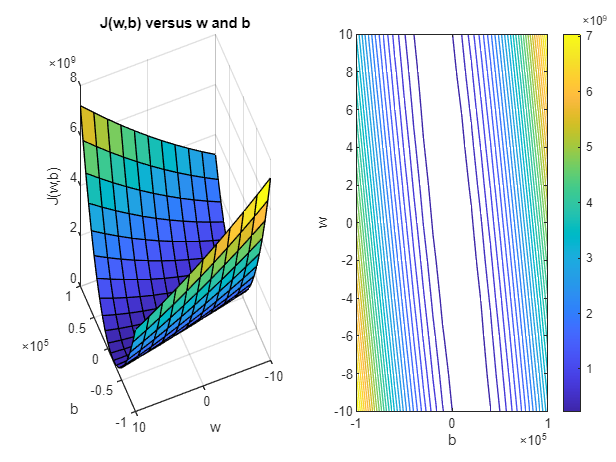

plotf = false; % Interactively plot f_{w,b}?

% Visualize the cost function
w_vec = -10:2:10; % weights
b_vec = -1e5:1e4:1e5; % bias

f = [];
J = [];
xPoints = linspace(min(data(:,1)),max(data(:,1)), 5);
numColors = numel(w_vec)*numel(b_vec);
cmap = lines(numColors);
idxc = 0;
figure
for idxw = 1:numel(w_vec)
    w = w_vec(idxw);
    for idxb = 1:numel(b_vec)
        b = b_vec(idxb);
    
        f{idxw,idxb} = w.*data(:,1) + b;
        J(idxw,idxb) = (1/(2*length(data(:,1))))*sum((f{idxw,idxb}-data(:,2)).^2);

        % Animated line
        if plotf
            yPoints = w.*xPoints + b;
            h = animatedline("Color",cmap(mod(idxc, size(cmap,1)) + 1, :));
            xlabel("normalized size (x)")
            ylabel("normalized price (y)")
            for k = 1:length(xPoints)
                addpoints(h, xPoints(k), w*xPoints(k) + b);
                drawnow
            end
            idxc = idxc + 1;
        end
    end
end

figure
tiledlayout(1, 2)
nexttile
surf(b_vec, w_vec, J)
xlabel('b')
ylabel('w')
zlabel('J(w,b)')
title('J(w,b) versus w and b')
view([247.80 34.00])

nexttile
contour(b_vec, w_vec, J, 30)
xlabel('b')
ylabel('w')
colorbar

Rather than manually trying to find the minimum value of the contour plot by picking a random ($w,b$) pair, which is time consuming and wouldn't work with more complex problems with very complex cost functions, we would look for an algorithm that can find the minimum ($w,b$) pair for that makes the cost function automatically/automagically minimum. There is an algorithm that does that called **gradient descent (GD)**, which is the one of the most important algorithm is AIML. Gradient descent and its variations is used not only in linear regression but almost every complex problem in AIML area.

**Note:**

- The cost equation provides a measure of how well your predictions match your training data.

- Minimizing the cost can provide optimal values of $w, b$.

## Gradient Descent (GD) Algorithm

Please note that the **squared loss cost function** ensures that the 'error surface' is convex like a soup bowl.It will always have a minimum that can be reached by following the gradient in all dimensions.

- Why?

The overview of what we are aiming with gradient descent;

- Have some function $J(w,b)$

- We want to minimize this function such that $\underset{w,b}{\mathrm{min}}\left\{ J(w,b) \right\} = \underset{w,b}{\mathrm{min}}\left\{ \frac{1}{2m}\sum_{i=1}^{m}  \left( wx^{(i)}+b- y^{(i)}\right)^2 \right\}$, where the $(w,b)$ pair that minimizes the given function becomes our solution. It turns out that the gradient descent algorithm can minimize not only linear regression cost function but any function that is convex.

#### Methodology

- We start with some initial guesses of $w$ and $b$ (random initialization). For instance, in linear regression it won't matter what the initial values are. Hence, the common choice is setting them to zero $w=0$ and $b=0$.

- Keep changing the parameters $w$ and $b$ a bit every time/iteration to reduce the cost $J(w,b)$.

- Repeat step 2 until (hopefully) we settle at or near minimum. Note that for some cost functions that might not have a bowl shape (non-convex) it is possible to have more than 1 minimum value.

For instance,

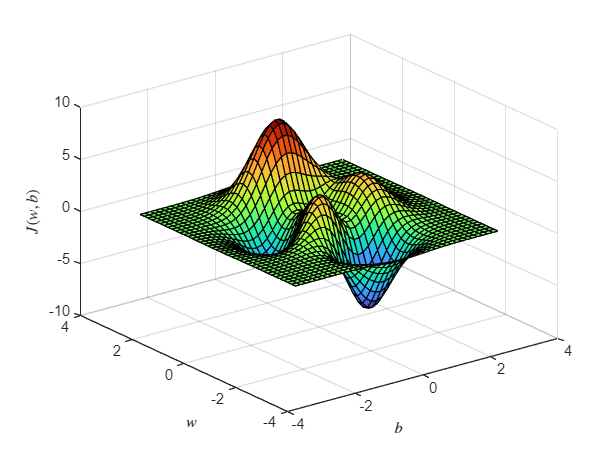

[X,Y,Z] = peaks(40);
figure
surf(X,Y,Z)
colormap turbo
xlabel('$b$','Interpreter','latex');
ylabel('$w$','Interpreter','latex');
zlabel('$J(w,b)$','Interpreter','latex');

What gradient descent algorithm does is it sits on a location and looks around and asks; "if I wanted to take a baby step in one direction to go downhill as quickly as possible to one of these valleys what direction should I choose to take a step?"

- If you want to walk down the hill as efficienctly as possible it turns out that the best direction is the direction towards the **steepest descent**.

In the following figure we can see two different randomly initiated gradient descent algorithms, which converge to different local minimum points.

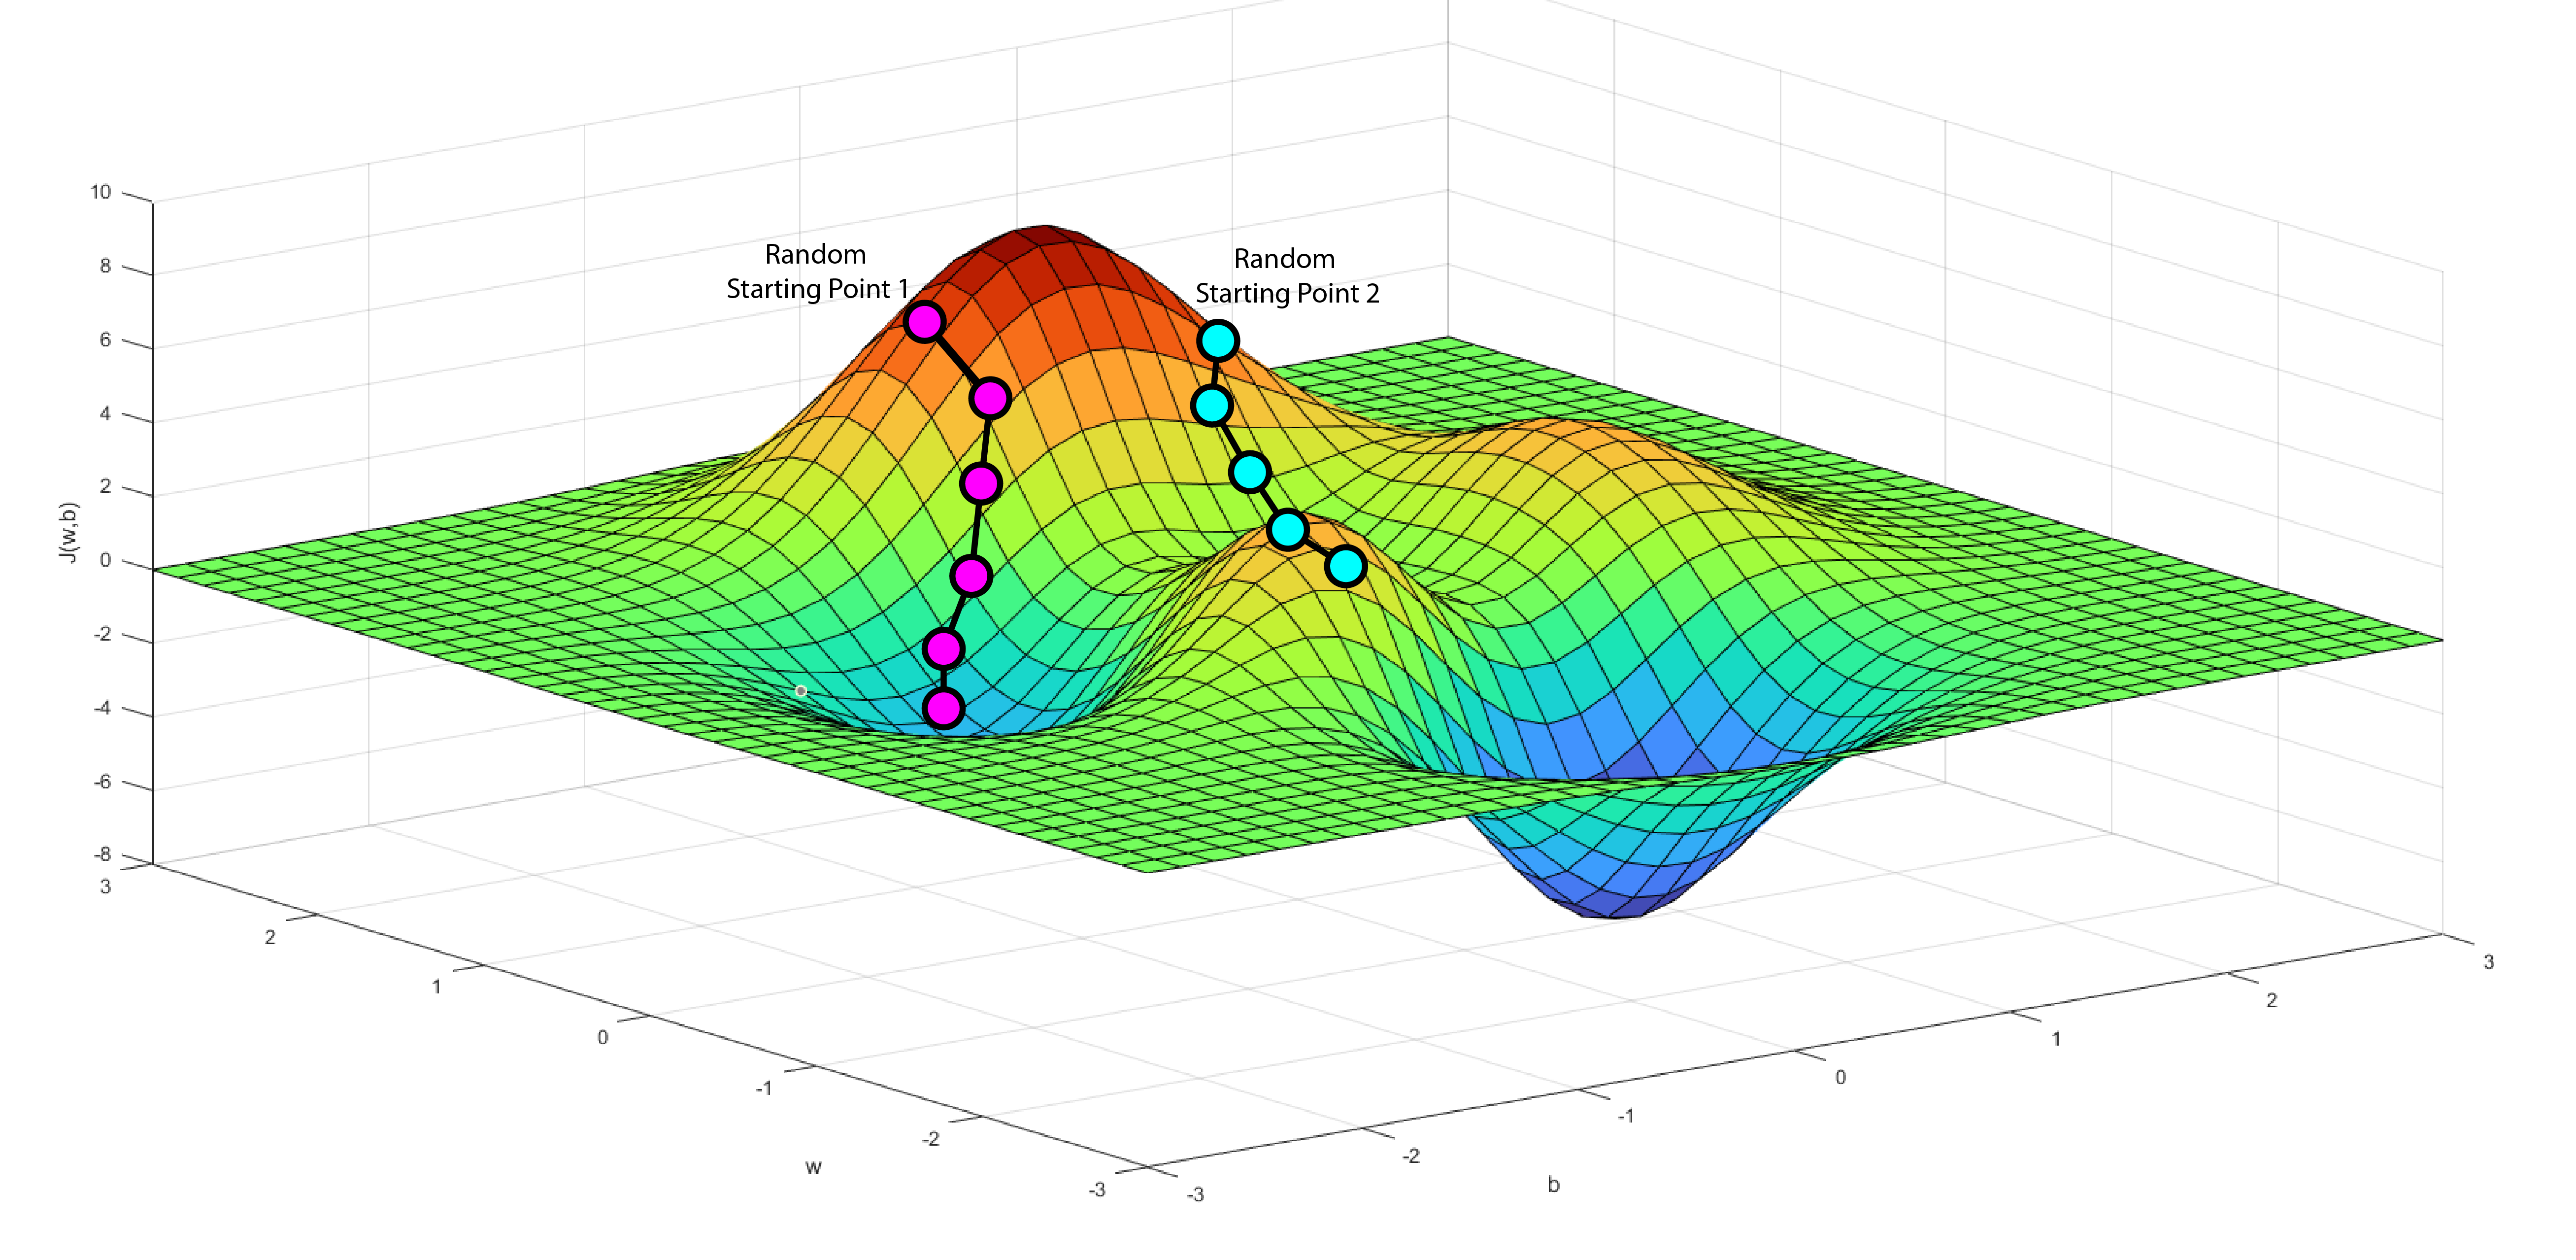

### Implementation

- In each step, update the weight(s) as follows: $w = w - \alpha \frac{\partial}{\partial w}J(w,b)$. It means that update the $w$ such that take the current value of the $w$ and substract the scaled derivative of the cost function with respect to $w$(Here, the equal sign represents the assignment operation). The parameter $\alpha$ is the **learning rate**, where $0 \leq \alpha \leq 1$. The learning rate controls how big a step you take towards the steepest descent. 

- In each step, also update the bias as follows:  $b = b - \alpha \frac{\partial}{\partial b}J(w,b)$.

- In gradient descent, we need to repeat the above steps until convergence. What is convergence? Convergence means that you reached the point at local/global minimum, where the parameters no longer change much in each step.

- There is one more subtle detail for correctly implementing the gradient descent; you will be updating the parameters $w$ and $b$, this update takes place for both parameters. In gradient descent, you want to simultaneously update the parameters $w$ and $b$.

**Correct way (simultaneous update) of implementing gradient descent:**

- 
$$w_\text{tmp} =  w - \alpha \frac{\partial}{\partial w}J(w,b)$$


- 
$$b_\text{tmp} =  b - \alpha \frac{\partial}{\partial b}J(w,b)$$


- 
$$w = w_\text{tmp}$$


- 
$$b = b_\text{tmp}$$


where $w_\text{tmp}$ and $b_\text{tmp}$ represents the temporay values for $w$ and $b$, respectively.

**Incorrect way of implmenting gradient descent:**

- 
$$w_\text{tmp} =  w - \alpha \frac{\partial}{\partial w}J(w,b)$$


- 
$$w = w_\text{tmp}$$


- 
$$b_\text{tmp} =  b - \alpha \frac{\partial}{\partial b}J(w,b)$$


- 
$$b = b_\text{tmp}$$


It turns out that even if you implement the gradient descent incorrectly, it would still work more less the same as the correct implementation, however, it is important to implement the algorithm according to the correct theoretical insight, which will ensure our long term success and will avoid unexpected problems in the future.

### Gradient Descent Intuition

In order to understand why the weight and bias update formulas

$w = w - \alpha \frac{\partial}{\partial w}J(w,b)$, 

$b = b - \alpha \frac{\partial}{\partial b}J(w,b)$ are used. Let's start with a simpler example, which contains one parameter. Thus, the cost function is in the form of $J(w)$ and the gradient descent based weight update formula becomes $w = w - \alpha \frac{\partial}{\partial w}J(w)$. Let's look at the previous simple single parameter cost function example and try to understand:

- What the learning rate ($\alpha$) does

- What the derivative part ($\frac{\partial}{\partial w}J(w,b)$ or $\frac{\partial}{\partial b}J(w,b)$) does

- Why they are multiplied

- Why the multiplication is substracted from the initial value and why it make sense

Since this example has only one parameter, the gradient descent algorithm looks like $w = w - \alpha \frac{\partial}{\partial w}J(w)$. And we try to minimize the cost function by only setting $w$ such that $\underset{w}{\mathrm{min}}\left\{J(w) \right\}$.

Let's initialize the gradient descent in some random points similar to the previous example with two parameters. In order to plot the gradient of the cost function, we should first calculate it. The cost function is given by

$J(w) = \frac{1}{2m}\sum_{i=1}^{m}\left( wx^{(i)}-y^{(i)} \right)^2$, where we need to calculate the $\frac{\partial}{\partial w}J(w) = \frac{\partial}{\partial w} \left( \frac{1}{2m}\sum_{i=1}^{m}\left( wx^{(i)}-y^{(i)} \right)^2 \right)$. 

Since we know that the derivative operation is distributive on the sum operation,


$$\frac{\partial}{\partial w}J(w) = \frac{1}{2m}\sum_{i=1}^{m}\frac{\partial}{\partial w}\left( wx^{(i)}-y^{(i)} \right)^2
=  \frac{1}{2m}\sum_{i=1}^{m}2\left( wx^{(i)}-y^{(i)} \right) \cdot x^{(i)}
= \frac{1}{m}\sum_{i=1}^{m}\left( wx^{(i)}-y^{(i)} \right) \cdot x^{(i)} \quad (3)
$$


Similarly, we can also obtain the rate of change of the cost function w.r.t. $b$ as follows:


$$\frac{\partial}{\partial b}J(w) = \frac{1}{2m}\sum_{i=1}^{m}\frac{\partial}{\partial w}\left( wx^{(i)}-y^{(i)} \right)^2
=  \frac{1}{2m}\sum_{i=1}^{m}2\left( wx^{(i)}-y^{(i)} \right)
= \frac{1}{m}\sum_{i=1}^{m}\left( wx^{(i)}-y^{(i)} \right) \quad (4)
$$


- Let's visualize the effect of the selected weight on the $J(w,b)$ and $\frac{\partial}{\partial w}J(w)$:

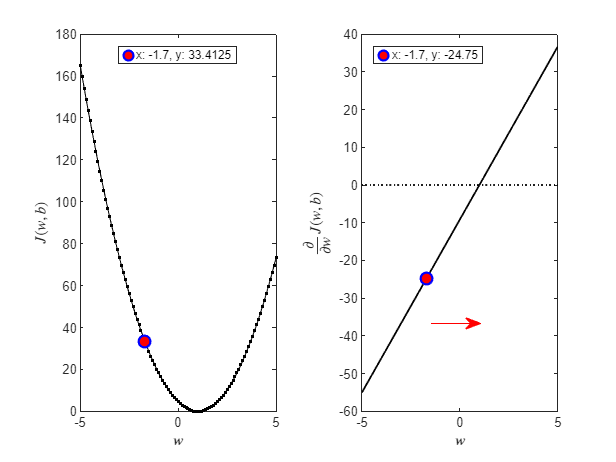

w_selected = -1.7;
hInteractiveGradPlot(w_selected);

### Selection of the Learning Rate

Selection of the learning rate, $\alpha$, is also really important in gradient descent implementation.

To understand what $\alpha$ is doing in gradient descent algorithm, let's explore the case where $\alpha$ is either too small or too large.

- If $\alpha$ is too small: The gradient descent will work but you end up incresing/decreasing $w$ but **very slowly**.It means that you will need a lot of steps (it will take a very long time) to reach to the minimum point.

- If $\alpha$ is too large: You update $w$ with a giant step and the cost might even increase over iterations (means you might go further from the minimum point). In this case gradient descent will overshoot and never reach the minimum, which means that it fails to **converge** to a solution but also **diverge**.

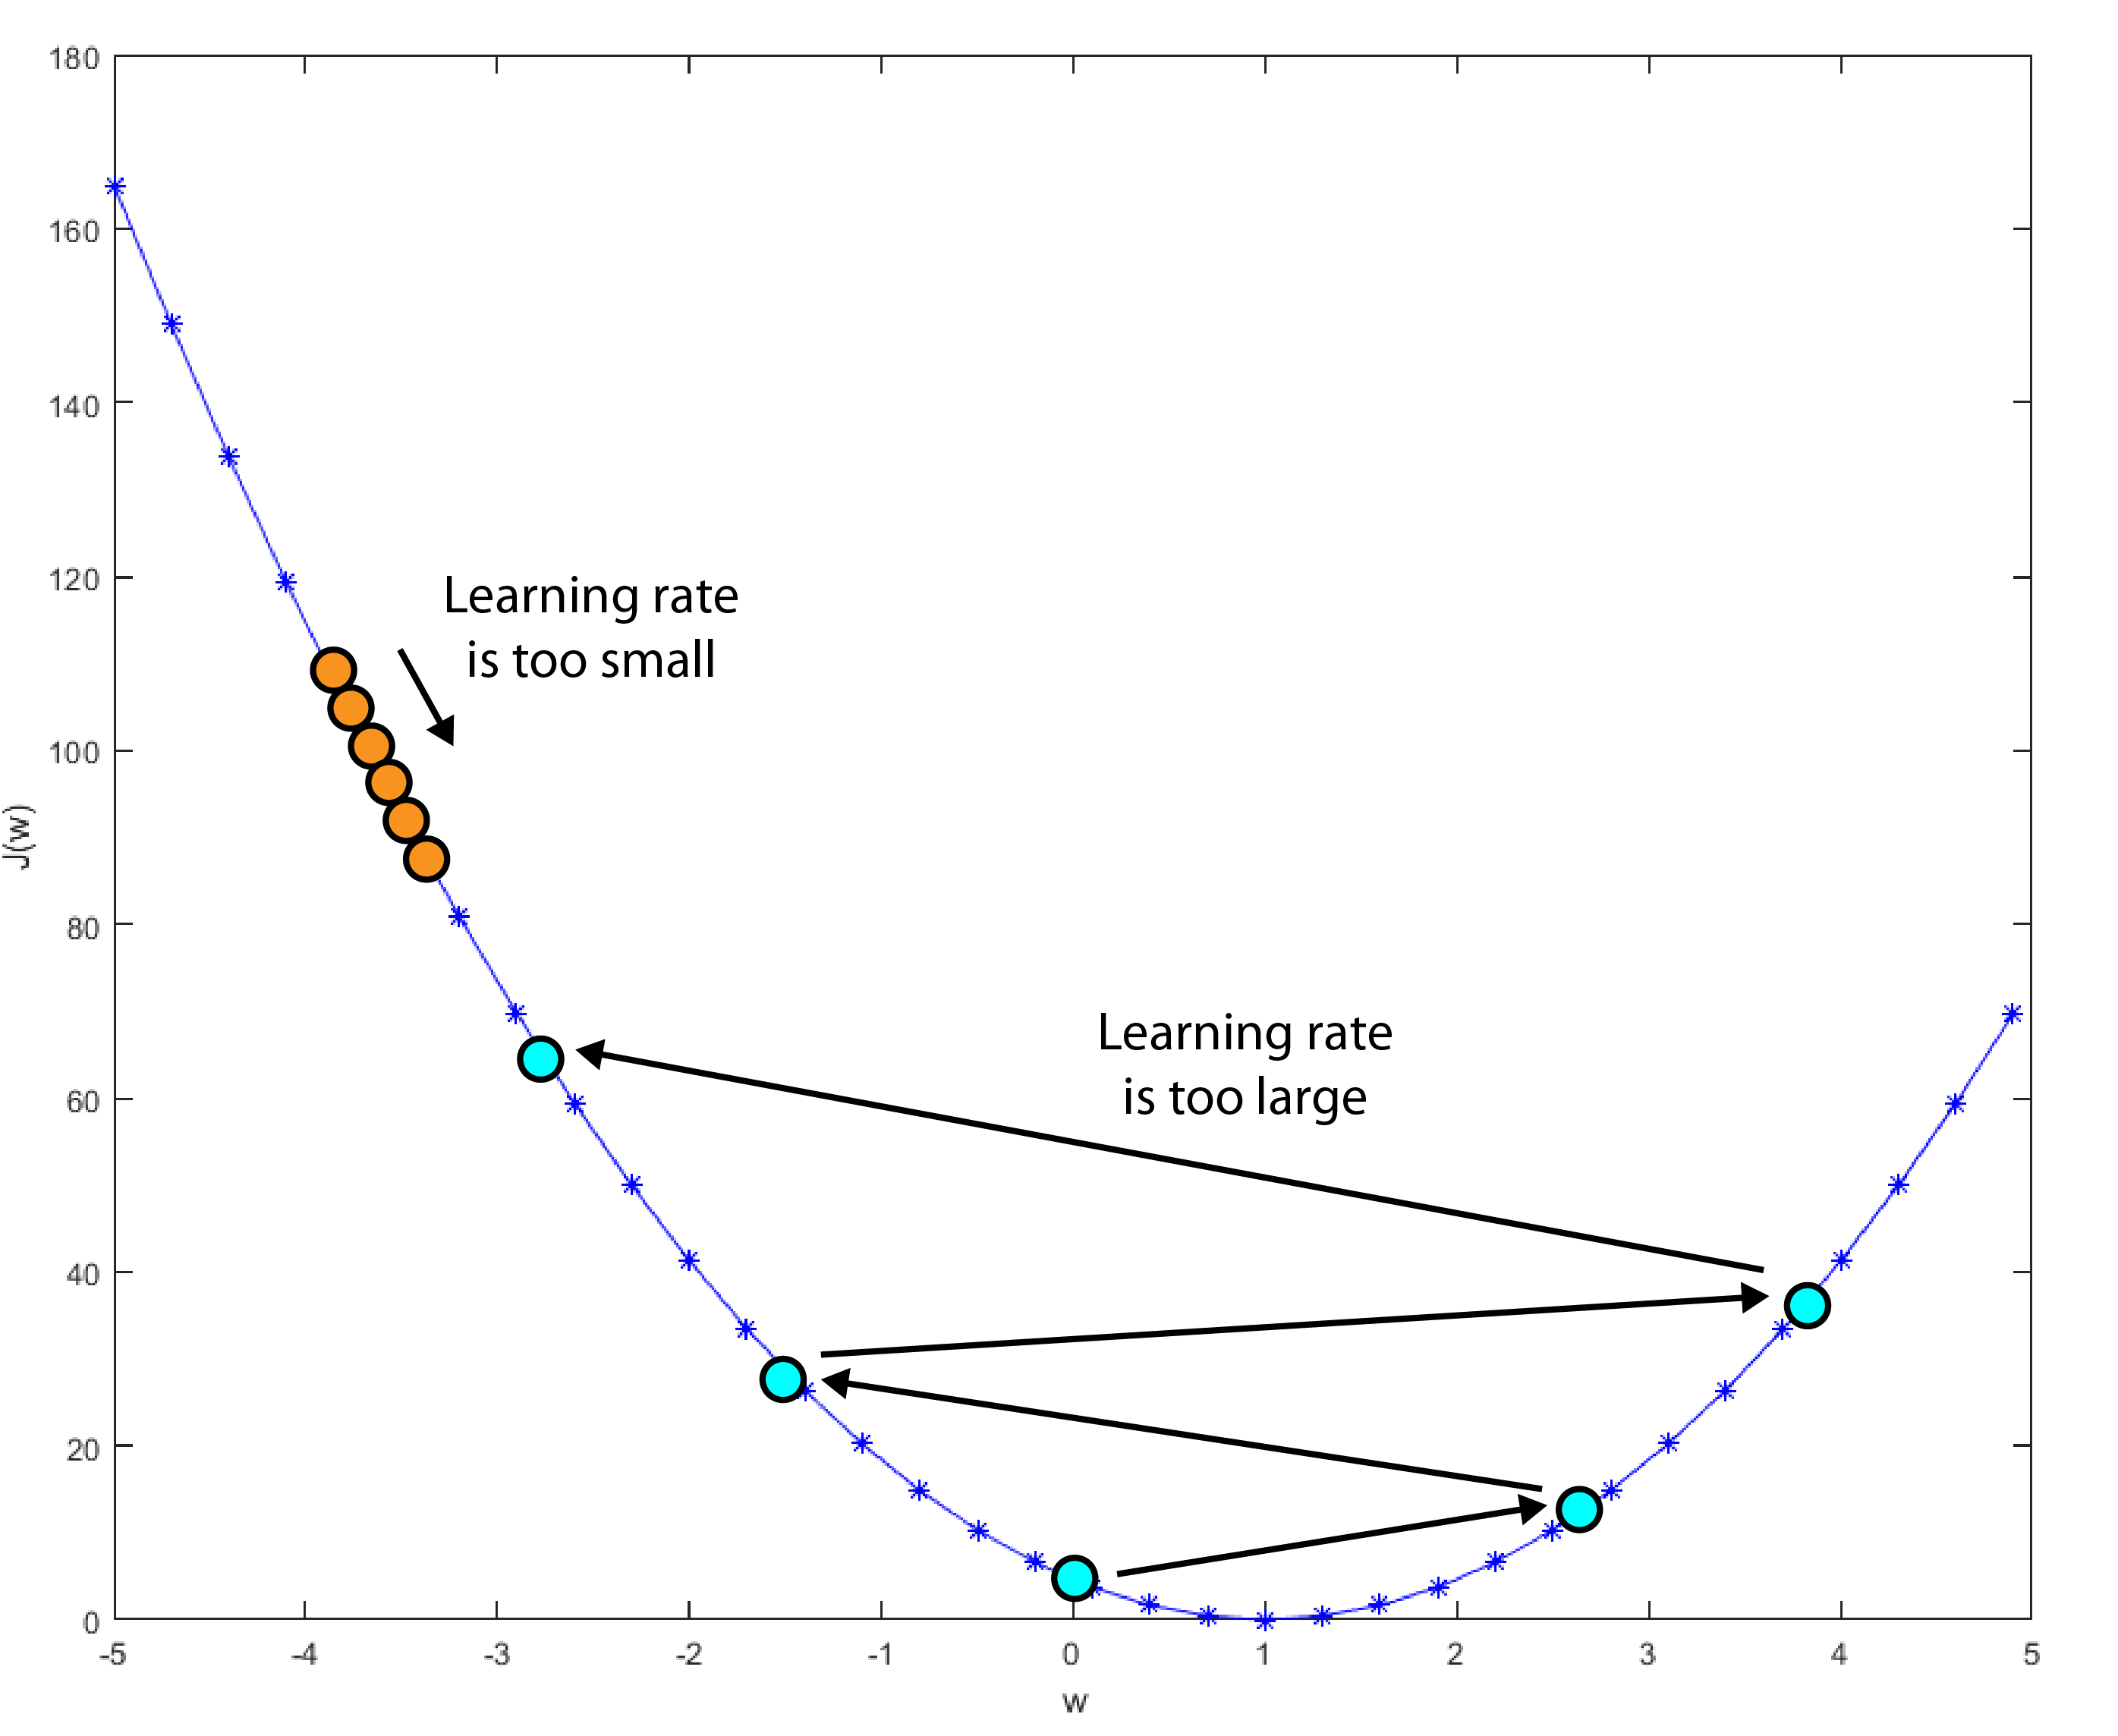

- If you are at a local minimum already, further gradient descent steps won't change anything since the derivative of the cost function equals to zero, which means that $w$ won't be updated.

It is important note that as we approach the local minimum, gradient descent will automatically take smaller steps due to the smaller derivative of the cost function. Therefore, gradient descent can reach local minimum without decresing the learning rate. **In other words, gradient descent can reach local minimum with a fixed learning rate.**

We can use gradient descent algorithm to minimize any cost function $J$, not just the mean squared error cost function that we are using for linear regression.

### Putting It Altogether

So far we had the following:

- **Linear regression model:** $f_{w,b}(x) = wx + b$

- **Cost function (squared error):** $J(w,b) = \frac{1}{2m}\sum_{i=1}^{m} \left( f_{w,b}(x^{(i)})-y^{(i)} \right)^2 = \frac{1}{2m}\sum_{i=1}^{m} \left( wx^{(i)}+b-y^{(i)} \right)^2$

- **Gradient descent algorithm:** Repeart until convergence $w = w - \alpha \frac{\partial}{\partial w}J(w,b)$ and $b = b - \alpha\frac{\partial}{\partial b} J(w,b)$

The natural question is how to calculate $w = w - \alpha \frac{\partial}{\partial w}J(w,b)$ and $b = b - \alpha\frac{\partial}{\partial b} J(w,b)$?

Let's start with $w = w - \alpha \frac{\partial}{\partial w}J(w,b)$. By using sum and chain rules we can find the partial derivate as follows:

- **Sum rule:** $\frac{\text{d}}{\text{d}x} \left( f(x) + g(x) \right) = \frac{\text{d}}{\text{d}x}f(x) + \frac{\text{d}}{\text{d}x}g(x)$

- **Chain rule:** $y = f\left( g(x) \right)$, if we make a substitution $u = g(x)$, it becomes $y = f(u)$, then $\frac{\text{d}y}{\text{d}x} = \frac{\text{d}y}{\text{d}u} \cdot \frac{\text{d}u}{\text{d}x}$

Then, 


$$w = w - \alpha \frac{\partial}{\partial w}\frac{1}{2m}\sum_{i=1}^{m} \left( wx^{(i)}+b - y^{(i)} \right)^2=  w - \alpha \frac{1}{2m}\sum_{i=1}^{m} \frac{\partial}{\partial w}\left( wx^{(i)}+b - y^{(i)} \right)^2 = w - \alpha \frac{1}{2m}\sum_{i=1}^{m}2\left( wx^{(i)}+b - y^{(i)} \right)\cdot x^{(i)} \\
\Rightarrow w = w - \alpha\frac{1}{m}\sum_{i=1}^{m}\left( wx^{(i)}+b - y^{(i)} \right)\cdot x^{(i)}$$


Similarly, 


$$w = w - \frac{\alpha}{m}\sum_{i=1}^{m}\left( wx^{(i)}+b - y^{(i)} \right)\cdot x^{(i)}$$



$$b = b - \alpha \frac{\partial}{\partial b}\frac{1}{2m}\sum_{i=1}^{m} \left( wx^{(i)}+b - y^{(i)} \right)^2=  b - \alpha \frac{1}{2m}\sum_{i=1}^{m} \frac{\partial}{\partial b}\left( wx^{(i)}+b - y^{(i)} \right)^2 =  b -  \alpha\frac{1}{2m}\sum_{i=1}^{m} 2\left( wx^{(i)}+b - y^{(i)} \right) \\
\Rightarrow b = b -  \alpha\frac{1}{m}\sum_{i=1}^{m} \left( wx^{(i)}+b - y^{(i)} \right)$$


Consequently, the gradient descent algorithm for linear regression becomes,

1) Randomly initialize $w$ and $b$ 

2) Repeat until convergence:

- 
$$w = w - \alpha\frac{1}{m}\sum_{i=1}^{m}\left( f_{w,b}(x^{(i)}) - y^{(i)} \right)\cdot x^{(i)} = w - \alpha\frac{1}{m}\sum_{i=1}^{m}\left( wx^{(i)}+b - y^{(i)} \right)\cdot x^{(i)}$$


- 
$$b = b - \alpha\frac{1}{m}\sum_{i=1}^{m} \left( f_{w,b}(x^{(i)}) - y^{(i)} \right) = b - \alpha\frac{1}{m}\sum_{i=1}^{m} \left( wx^{(i)}+b - y^{(i)} \right)$$


where you want to update $w$ and $b$ simultaneously.

**As long as the learning rate is chosen properly, gradient descent will find the global minimum for the squared error cost function (as it is convex).**

### Running Gradient Descent

If every step of the gradient descent algorithm uses all the training samples it is called **batch gradient descent**. Let's see what happens if we run batch gradient descent algorithm on linear regression problem.

Let's run the batch gradient descent algorithm and visualize the linear regression model $f_{w,b}(x) = wx+b$ and cost function $J(w,b)$ for each iteration

% Batch gradient descent implementation
x = 1:5;
y = x-2;
%x = (data(:,1)-min(data(:,1)))/(max(data(:,1))-min(data(:,1)));
%y = (data(:,2)-min(data(:,2)))/(max(data(:,2))-min(data(:,2)));
alpha = 0.015; % learning rate is between [0 1], best = 0.015, too large = 0.17 too small = 1e-5.
verbose = true;

 
[J_vec,w_vec,b_vec] = batchGradientDescent(x,y,alpha,verbose);

Iteration #0 | Cost: 24.7051
Iteration #20 | Cost: 7.1179
Iteration #40 | Cost: 6.4243
Iteration #60 | Cost: 5.8039
Iteration #80 | Cost: 5.2434
Iteration #100 | Cost: 4.7371
Iteration #120 | Cost: 4.2796
Iteration #140 | Cost: 3.8663
Iteration #160 | Cost: 3.493
Iteration #180 | Cost: 3.1556
Iteration #200 | Cost: 2.8509
Iteration #220 | Cost: 2.5756
Iteration #240 | Cost: 2.3269
Iteration #260 | Cost: 2.1021
Iteration #280 | Cost: 1.8991
Iteration #300 | Cost: 1.7157
Iteration #320 | Cost: 1.55
Iteration #340 | Cost: 1.4004
Iteration #360 | Cost: 1.2651
Iteration #380 | Cost: 1.143
Iteration #400 | Cost: 1.0326
Iteration #420 | Cost: 0.93286
Iteration #440 | Cost: 0.84277
Iteration #460 | Cost: 0.76138
Iteration #480 | Cost: 0.68786
Iteration #500 | Cost: 0.62143
Iteration #520 | Cost: 0.56142
Iteration #540 | Cost: 0.5072
Iteration #560 | Cost: 0.45822
Iteration #580 | Cost: 0.41397
Iteration #600 | Cost: 0.37399
Iteration #620 | Cost: 0.33788
Iteration #640 | Cost: 0.30525
Iteratio

numIter = numel(J_vec)-1;

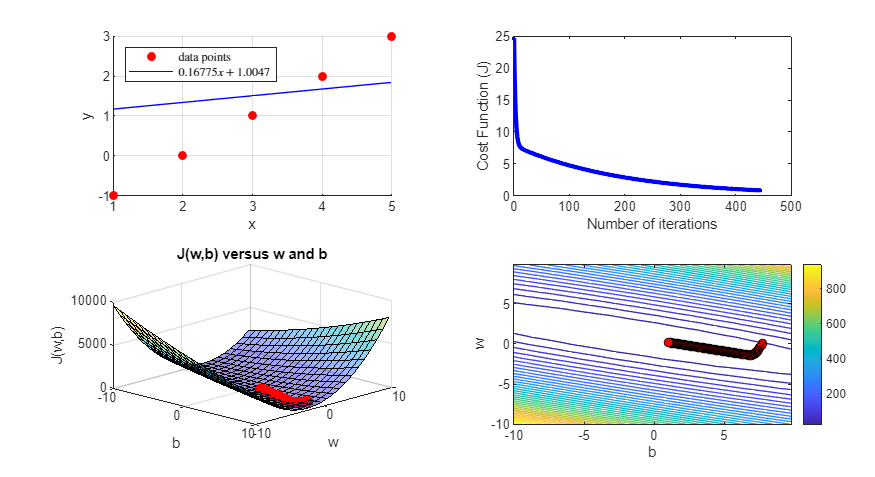

idxIter =445;
plotMode = "cumulative";
hInteractiveLinearRegression(x,y,w_vec,b_vec,J_vec,idxIter,plotMode)
set(gcf,'position',[0 0 1100 600]);

## Local Functions

function [J_vec,w_vec,b_vec] = batchGradientDescent(x,y,alpha,verbose)

% Step 1: Randomly initialize the parameters w and b
stopFlag = false;
m = length(x);
iter = 0; % iteration number
J_vec = [];
w_vec = [];
b_vec = [];
w = randsrc(1,1,-10:0.001:10);
b = randsrc(1,1,-10:0.001:10);
condStop = 1e-3;
maxIter = 1e4; % Maximum number of iterations that will terminate the search

% Step 2: Update w and b by using BGD until the convergence criteria is met
while ~stopFlag
    dJdw = 0;
    dJdb = 0;
    
    for i = 1:m
        dJdw = dJdw + (1/m)*( (w*x(i)+b-y(i))*x(i) );
        dJdb = dJdb + (1/m)*( (w*x(i)+b-y(i)) );
    end
    
    w = w - alpha*dJdw; % update w
    b = b - alpha*dJdb; % update b

    w_vec = cat(1,w_vec,w); % record w history
    b_vec = cat(1,b_vec,b); % record b history

    % Calculate the cost function
    J_tmp = 0;
    for i = 1:m
        J_tmp = J_tmp + (w*x(i)+b-y(i))^2;
    end
    J = (1/(2*m))*J_tmp;
    J_vec = cat(1,J_vec,J);

    if verbose
        if mod(iter,20) == 0
            disp(['Iteration #',num2str(iter),' | Cost: ',num2str(J)])
        end
    end

    % if the cost function is small enough stop iterating (convergence)
    % OR if the number of iterations reaches to a limit stop iterating (divergence)
    if iter == maxIter - 1 || J <= condStop 
        stopFlag = true;
        disp("==================================")
        if iter == maxIter - 1
            disp(['BGD Stopped: max number of iterations ',sprintf('(%d)',iter)])
        else
            disp(['BGD Stopped: minimized cost function ',sprintf('(%f.2)',J)])
        end
    end

    iter = iter + 1; % update the iteration number
end

end

## References

Coursera "[Supervised Machine Learning: Regression and Classification](https://www.coursera.org/learn/machine-learning/)"